### Assess and visualize impacts of using different inputs

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\CalibrationPeriodandInputsAssessmentPlot'
cd data\input\

### Weekly

load('BFLAT_weeklyLEann_135617.mat')
load('BFLAT_weeklyLEann_3561017.mat')
load('BFLAT_weeklyLEann_3561317.mat')
load('BFLAT_weeklyLEann_35111417.mat')
load('BFLAT_weeklyLEann_356111417.mat')
load('BFLAT_weeklyLEann_358111417.mat')
load('BFLAT_weeklyLEann_1356101317.mat')
load('BFLAT_weeklyLEann_2356111417.mat')
load('BFLAT_weeklyLEann_35611121417.mat')
load('BFLAT_weeklyLEann_35611131417.mat')
load('BFLAT_weeklyLEann_3561114151617.mat')
load('BFLAT_weeklyLEann_23561011131517.mat')

load('Bflat_30minLEann_23561011131517.mat')
BFLAT_weeklyLEann_23561011131517 = retime(Bflat_30minLEann_23561011131517, 'weekly','sum');

### Full

load('Bflat_30minLEann_135617.mat')
% load('Bflat_30minLEann_3561017.mat')
load('Bflat_30minLEann_3561317.mat')
load('Bflat_30minLEann_35111417.mat')
load('Bflat_30minLEann_356111417.mat')
load('Bflat_30minLEann_358111417.mat')
load('Bflat_30minLEann_1356101317.mat')
load('Bflat_30minLEann_2356111417.mat')
% load('Bflat_30minLEann_35611121417.mat')
load('Bflat_30minLEann_35611131417.mat')
BFLAT_weeklyLEann_35611131417 = retime(Bflat_30minLEann_35611131417, "weekly",'sum');
load('Bflat_30minLEann_3561114151617.mat')

load('Bflat30min.mat')
load('BflatEdCov.mat')
bflatEdCovBackup = bflatEdCov;

load("bflatDaily_Evap.mat")
BflatWeekly = retime(BflatDaily,"weekly",'sum');

% load('BFLAT_weeklyLEann_23561011131517.mat')
load('Bflat_30minLEann_23561011131517.mat')


###  Temperature Weekly

load('BFLAT_weeklyLEann_23561011131517_clippedBelow30C.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedBelow25C.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedBelow20C.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedBelow15C.mat')

### Humidity Weekly

load('BFLAT_weeklyLEann_23561011131517_clippedabove70humidity.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedabove60humidity.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedabove50humidity.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedabove40humidity.mat')
load('BFLAT_weeklyLEann_23561011131517_clippedabove30humidity.mat')

# Figure S5

figure
t= tiledlayout (4,1);

### Full time period - only SW radiation

nexttile
hold on

plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN_albedoPiecewise, ":", 'color', [0 0.4470 0.7410], ...
    'linewidth', 2,  "DisplayName", "E_eLow")
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN_albedoPiecewise2, "-.", 'color', [0.9290 0.6940 0.1250], ...
    'linewidth', 2,  "DisplayName", "E_eHigh")
%%less preferred
plot(BFLAT_weeklyLEann_35111417.Date_Time_MDT ,BFLAT_weeklyLEann_35111417.LEann_prctile50, 'displayname', 'base: air temp., rel. humidity, in & out SW, time of day') % no wind input - slighly higher winter evap, but relatively minor
%%prefferred
plot(BFLAT_weeklyLEann_356111417.Date_Time_MDT ,BFLAT_weeklyLEann_356111417.LEann_prctile50, "--", 'color', [0.6350 0.0780 0.1840], ...
    'linewidth', 2,  'displayname', 'base, wind speed')
plot(BFLAT_weeklyLEann_2356111417.Date_Time_MDT ,BFLAT_weeklyLEann_2356111417.LEann_prctile50, 'displayname', 'base, air pres., wind speed') % %Slighly lower winter peaks, otherwise very similiar to one without 
%%less preferred
plot(BFLAT_weeklyLEann_35611121417.Date_Time_MDT ,BFLAT_weeklyLEann_35611121417.LEann_prctile50, 'displayname', 'base, soil temp., wind speed')% %Soil Temp -  mostly similiar, slighly lower calculated evaporation
% plot(BFLAT_weeklyLEann_358111417.Date_Time_MDT ,BFLAT_weeklyLEann_358111417.LEann_prctile50, 'displayname', '358111417') %wind gust - very similiar to just wind input

legend('location', 'bestoutside')
xticklabels([]) 
ylim([-1,20])
xlim(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT([1,end]))
ylabel('E_eANN (mm week^-^1)')
xline(BflatDaily.Date_Time_MDT(230+365),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(673),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(251),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');

### Limited time period - LW radiation - all poor relative to albedo calibrated PM

nexttile
hold on
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN_albedoPiecewise, ":", 'color', [0 0.4470 0.7410], ...
    'linewidth', 2,  "DisplayName", "E_eLow")
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN_albedoPiecewise2, "-.", 'color', [0.9290 0.6940 0.1250], ...
    'linewidth', 2,  "DisplayName", "E_eHigh")

plot(BFLAT_weeklyLEann_3561317.Date_Time_MDT ,BFLAT_weeklyLEann_3561317.LEann_prctile50, 'displayname', 'base: air temp., rel. humidity, wind speed, time of day')
plot(BFLAT_weeklyLEann_3561317.Date_Time_MDT ,BFLAT_weeklyLEann_3561317.LEann_prctile50, 'displayname', 'base, net LW')
plot(BFLAT_weeklyLEann_1356101317.Date_Time_MDT ,BFLAT_weeklyLEann_1356101317.LEann_prctile50, 'displayname', 'base, net rad., net SW & LW')
plot(BFLAT_weeklyLEann_35611131417.Date_Time_MDT ,BFLAT_weeklyLEann_35611131417.LEann_prctile50, 'displayname', 'base, net LW, in & out SW,')
plot(BFLAT_weeklyLEann_3561114151617.Date_Time_MDT ,BFLAT_weeklyLEann_3561114151617.LEann_prctile50, 'displayname', 'base, in & out SW, in & out LW')
%%preferred
plot(BFLAT_weeklyLEann_23561011131517.Date_Time_MDT ,BFLAT_weeklyLEann_23561011131517.LEann_prctile50,'color', 'blue','linewidth', 2, 'displayname', 'base, air pres., net & in SW, net & out LW') 

ylim([-1,20])
xlim(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT([1,end]))
ylabel('E_eANN (mm week^-^1)')
legend('location', 'bestoutside')
xticklabels([])
xline(BflatDaily.Date_Time_MDT(230+365),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(673),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(251),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');

## Temperature Weekly Datasets

nexttile
hold on

plot(BFLAT_weeklyLEann_23561011131517.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517.LEann_prctile50,'color', 'blue','linewidth',2, 'displayname', 'original')
plot(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedBelow15C.LEann_prctile50, 'displayname', '<15 ^oC clip')
plot(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedBelow20C.LEann_prctile50, 'displayname', '<20 ^oC clip')
plot(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedBelow25C.LEann_prctile50, 'displayname', '<25 ^oC clip')
plot(BFLAT_weeklyLEann_23561011131517_clippedBelow30C.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedBelow30C.LEann_prctile50, 'displayname', '<30 ^oC clip')
plot(BFLAT_weeklyLEann_23561011131517.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517.LEann_prctile50,'color', 'blue','linewidth',2, 'HandleVisibility','off')

legend('location', 'bestoutside')
ylabel('E_eANN (mm week^-^1)')
ylim([-2,16])
xlim(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT([1,end]))
xticklabels([])
xline(BflatDaily.Date_Time_MDT(230+365),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(673),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(251),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');

## Humidity Weekly Datasets 

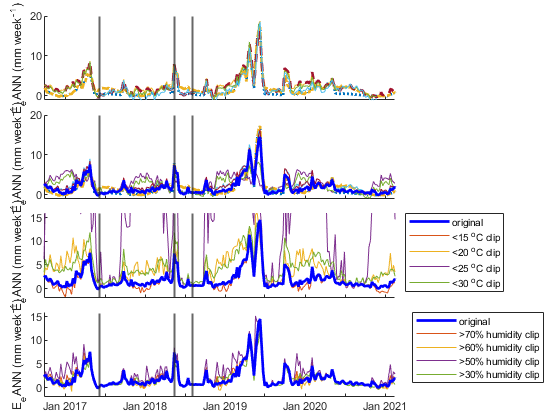

nexttile
hold on
plot(BFLAT_weeklyLEann_23561011131517.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517.LEann_prctile50,'color', 'blue','linewidth',2, 'displayname', 'original')
plot(BFLAT_weeklyLEann_23561011131517_clippedabove70humidity.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedabove70humidity.LEann_prctile50, 'displayname', '>70% humidity clip')
plot(BFLAT_weeklyLEann_23561011131517_clippedabove70humidity.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedabove60humidity.LEann_prctile50, 'displayname', '>60% humidity clip')
plot(BFLAT_weeklyLEann_23561011131517_clippedabove70humidity.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedabove50humidity.LEann_prctile50, 'displayname', '>50% humidity clip')
% plot(BFLAT_weeklyLEann_23561011131517.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedabove40humidity.LEann_prctile50, 'displayname', '> 40% clip')
plot(BFLAT_weeklyLEann_23561011131517_clippedabove70humidity.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517_clippedabove30humidity.LEann_prctile50, 'displayname', '>30% humidity clip')
plot(BFLAT_weeklyLEann_23561011131517.Date_Time_MDT, BFLAT_weeklyLEann_23561011131517.LEann_prctile50,'color', 'blue','linewidth',2, 'HandleVisibility','off')

legend('location', 'bestoutside')
ylabel('E_eANN (mm week^-^1)')
ylim([-2,16])
xlim(BFLAT_weeklyLEann_23561011131517_clippedBelow25C.Date_Time_MDT([1,end]))
xline(BflatDaily.Date_Time_MDT(230+365),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(673),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(251),'linewidth', 1.5, 'displayname', '0 evaporation','HandleVisibility','off');
t.TileSpacing = 'compact';
t.Padding = 'compact';

cd ..\output\
print('ANNinputsAss', '-fillpage','-dpdf')

## Figure S4

figure
t = tiledlayout(3,1);
nexttile;

### EddyCovTrainining data and resulting model

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_35611131417,'Type','left');
bflatEdCov = retime(bflatEdCov,"hourly", @mean);
hold on
plot(bflatEdCov.Date_Time_MDT, bflatEdCov.Evaporation_mm30min*2,'color', 'blue', ...
    'linewidth', 1.5, 'displayname', 'Eddy Covariance')

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_23561011131517,'Type','left');
bflatEdCov = retime(bflatEdCov,"hourly", @mean);
plot(bflatEdCov.Date_Time_MDT, bflatEdCov.LEann_prctile50*2,'color', 'red', 'displayname', 'E_eANN (air pressure, in & net SW, out & net LW)') %multiply by two to make up for mean value.. 

xlim(bflatEdCov.Date_Time_MDT([260,end]))
legend('location', 'northoutside')
ylim([-0.02 0.2])
ylabel('evaporation rate (mm hour^-^1)')


### Cumulative sum EddyCovTrainining data and resulting model

nexttile;

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_23561011131517,'Type','left');

bflatEdCov.LEann_prctile75cumsum = cumsum(bflatEdCov.LEann_prctile75singlemodel);
bflatEdCov.LEann_prctile75cumsum(2393) = 0;
bflatEdCov.LEann_prctile25cumsum = cumsum(bflatEdCov.LEann_prctile25singlemodel);
bflatEdCov.LEann_prctile25cumsum(2393) = 0;

hold on
plot(bflatEdCov.Date_Time_MDT, cumsum(bflatEdCov.Evaporation_mm30min),'color', 'blue','linewidth', 1.5, 'displayname', 'Eddy Covariance')
plot(bflatEdCov.Date_Time_MDT, cumsum(bflatEdCov.LEann_prctile50), 'color', 'red', 'linewidth', 2,'displayname', 'air pressure, in & net SW, out & net LW') %multiply by two to make up for mean value.. 

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_35611131417,'Type','left');
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.LEann_prctile50, "linear")), 'displayname', 'in & out SW') %multiply by two to make up for mean value.. 

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_2356111417,'Type','left');
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.LEann_prctile50, "linear")), 'displayname', 'air pressure, in & out SW') %multiply by two to make up for mean value.. 

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_35611131417,'Type','left');
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.LEann_prctile50, "linear")), 'displayname', 'in & out SW, soil temp') %multiply by two to make up for mean value.. 

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_3561317,'Type','left');
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.LEann_prctile50, "linear")), 'displayname', 'net LW') %multiply by two to make up for mean value.. 

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_1356101317,'Type','left');
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.LEann_prctile50, "linear")), 'displayname', 'net rad., net SW, net LW') %multiply by two to make up for mean value.. 

bflatEdCov = bflatEdCovBackup;
bflatEdCov = outerjoin(bflatEdCov,Bflat_30minLEann_35611131417,'Type','left');
plot(bflatEdCov.Date_Time_MDT,cumsum(bflatEdCov.LEann_prctile50), 'displayname', 'in SW,net LW,out SW') %multiply by two to make up for mean value.. 

xlim(bflatEdCov.Date_Time_MDT([22,end]))

legend('location', 'eastoutside')
ylim([0 9.5])
ylabel('cumulative evaporation (mm)')

### Calibration Period Cumulative Sum Comparison

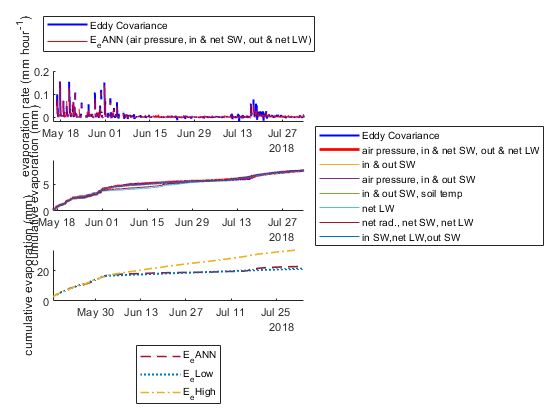

nexttile
bflatEdCov = bflatEdCovBackup;

bflatEdCov = BflatDaily(595:679,:);
bflatEdCov.PET_m_CN_albedoPiecewise2 = cumsum(bflatEdCov.PET_m_CN_albedoPiecewise2);
bflatEdCov.PET_m_CN_albedoPiecewise = cumsum(bflatEdCov.PET_m_CN_albedoPiecewise);
bflatEdCov.LEann_prctile50 = cumsum(bflatEdCov.LEann_prctile50);

hold on
plot(bflatEdCov.Date_Time_MDT, bflatEdCov.LEann_prctile50,"--", 'color', [0.6350 0.0780 0.1840], ...
    'linewidth', 1.2,  'displayname', "E_eANN");
plot(bflatEdCov.Date_Time_MDT, bflatEdCov.PET_m_CN_albedoPiecewise,":", 'color', [0 0.4470 0.7410], ...
    'linewidth', 1.5,  "DisplayName", "E_eLow")
plot(bflatEdCov.Date_Time_MDT, bflatEdCov.PET_m_CN_albedoPiecewise2,"-.", 'color', [0.9290 0.6940 0.1250], ...
    'linewidth', 1.2,  "DisplayName", "E_eHigh")

bflatEdCov = bflatEdCovBackup;
xlim(bflatEdCov.Date_Time_MDT([22,end]))
ylim([0 34])

legend('location', 'southoutside')
ylabel('cumulative evaporation (mm)')

t.TileSpacing = 'compact';
t.Padding = 'compact';
cd ..\output\
print('CalPerMethodsContrast', '-fillpage','-dpdf') %'-bestfit'